## Kasami序列的仿真

@Copyright (c) zihan xing

使用kasami序列对波形进行了设计

发射信号参数

clc;clear;close all;
addpath('funcs');  % 将 functions 文件夹添加到路径
fs = 4e3;
fc = 1.5e3;
Ts = 1/fs;
B = 200;    % 带宽（Hz）

### Kasami序列信号

m=4; 
oct = 23;
gen = [1 0 0 1 1];

seqs = lkasami(oct,gen);%生成gold序列

First 4 sequences are small set Kasami


kasami1 = seqs(6,:);
kasami2 = seqs(15,:);
kasami3 = seqs(25,:);
disp(kasami1)

     0     0     0     0     0     1     0     1     0     0     1     1     0     1     1



%采用相位编码，设3.1s的CW信号
t_scale = 0:1/fs:3.1-1/fs;
P = exp(1j*2*pi*fc*t_scale).';
%2s的信号，15个二进制数
n = length(kasami1 )    %频率变化数

n = 15

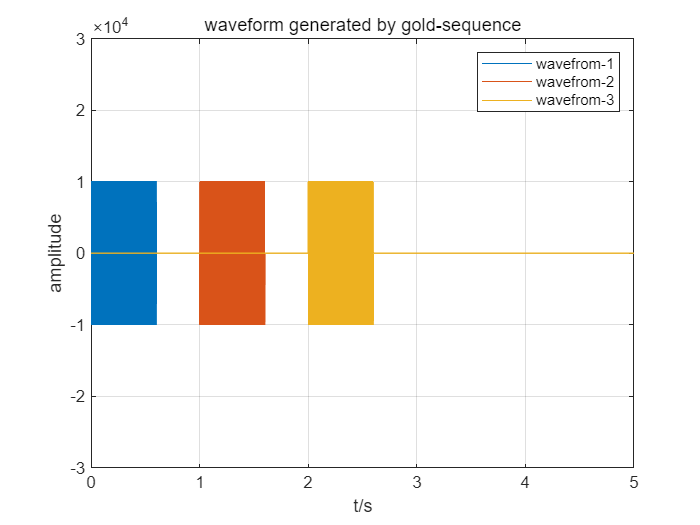


Tp = 0.6/n;                %则子脉冲长度Tp
N_subpulse = round(Tp*fs);       % 子脉冲采样点数

t_subpulse = 0 :1/fs:Tp-1/fs; % 时间序列，采样间隔为 1/fs

for kk = 1:n % 遍历每个变化点
    Nx1 = (kk-1)*N_subpulse+1;   % 当前跳频点的起始索引
    Nx11 = (kk)*N_subpulse;      % 当前跳频点的结束索引
    kasami_pulse1(Nx1:Nx11) = 1e4*exp(1i*(2*pi*fc*t_subpulse+pi*kasami1(kk))); % 生成信号的复包络,
    kasami_pulse2(Nx1:Nx11) = 1e4*exp(1i*(2*pi*fc*t_subpulse+pi*kasami2(kk))); % 生成信号的复包络,
    kasami_pulse3(Nx1:Nx11) = 1e4*exp(1i*(2*pi*fc*t_subpulse+pi*kasami3(kk))); % 生成信号的复包络,
end    

%三个不同的匹配滤波器
matchedFilter1 = kasami_pulse1;
matchedFilter2 = kasami_pulse2;
matchedFilter3 = kasami_pulse3;

TIME = 250;
n = round(0.6*fs);
paddled1 =  [kasami_pulse1 zeros(1,round(TIME*fs)-n)];                    %0~0.6ss存在信号
paddled2  = [zeros(1,1*fs) kasami_pulse2 zeros(1,round((TIME-1)*fs)-n)];%1~1.6S存在信号
paddled3  = [zeros(1,2*fs) kasami_pulse3 zeros(1,round((TIME-2)*fs)-n)];%2~2.6s存在信号


% 定义时间参数
t = (0:1/fs:TIME - 1/fs).'; % 时间向量，这里生成0到100秒的时间序列，采样间隔为1/fs
N = length(t);
f = -fs/2:fs/N:fs/2-fs/N;
figure
plot(t, real(paddled1));hold on;
plot(t, real(paddled2));hold on;
plot(t, real(paddled3));hold on;
xlabel('t/s');ylabel('amplitude');title('waveform generated by gold-sequence');
grid on;legend('wavefrom-1','wavefrom-2','wavefrom-3');
axis([0,5,-3e4,3e4]);


%计算三个波形的能量
E1 = sum(abs(kasami_pulse1).^2);E2 = sum(abs(kasami_pulse2).^2);E3 = sum(abs(kasami_pulse3).^2);
disp(E1);disp(E2);disp(E3);

   2.4000e+11

   2.4000e+11

   2.4000e+11



### 绘制模糊函数

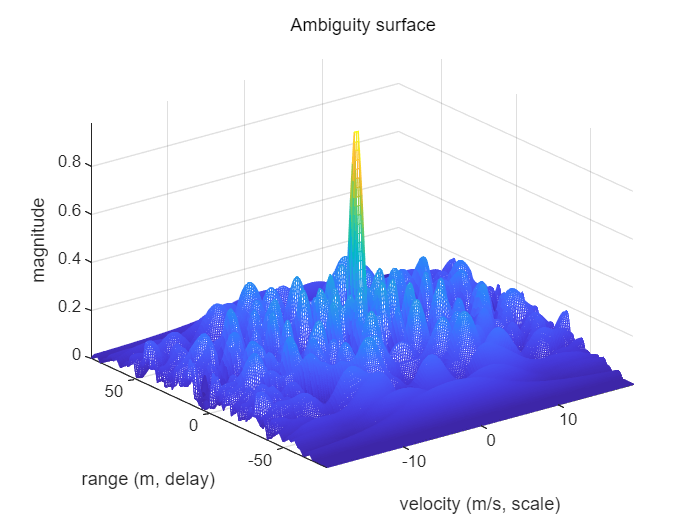

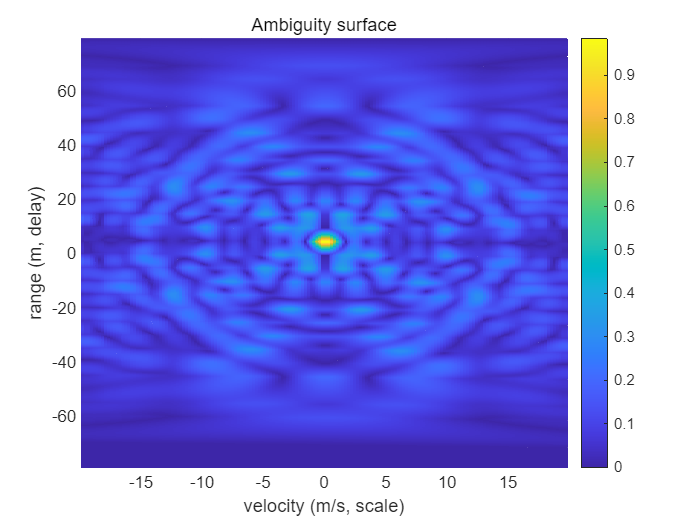

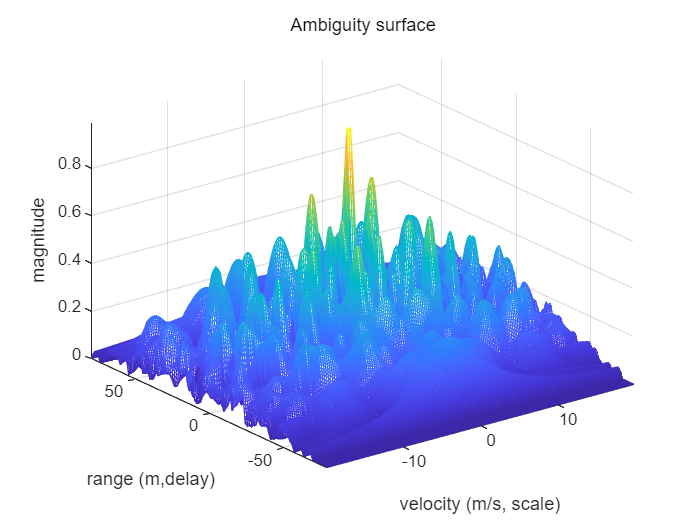

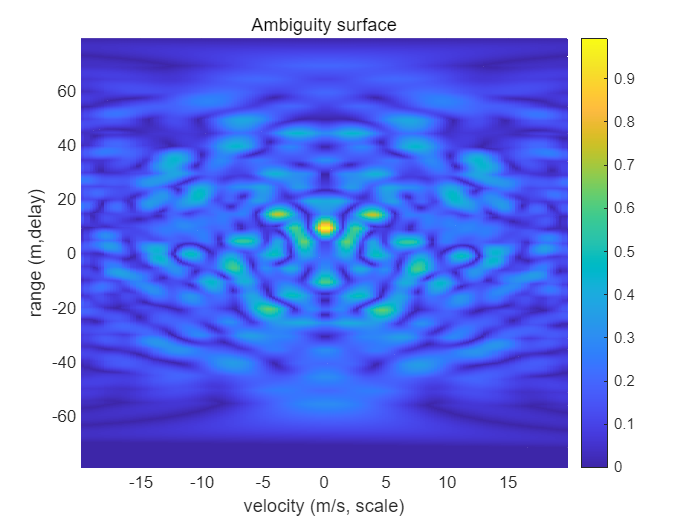

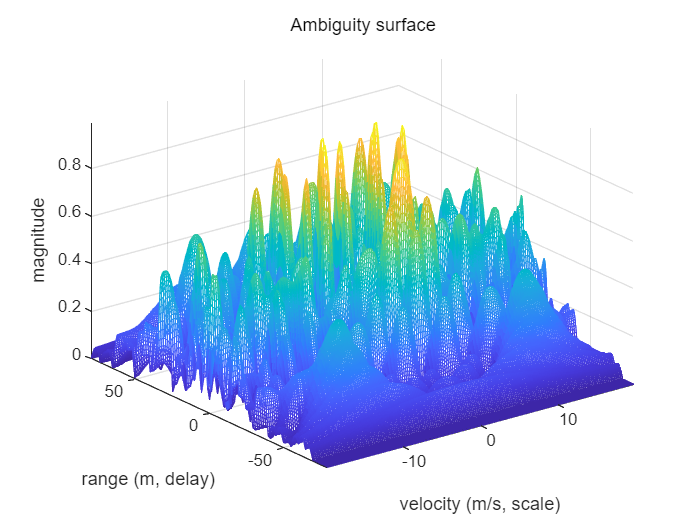

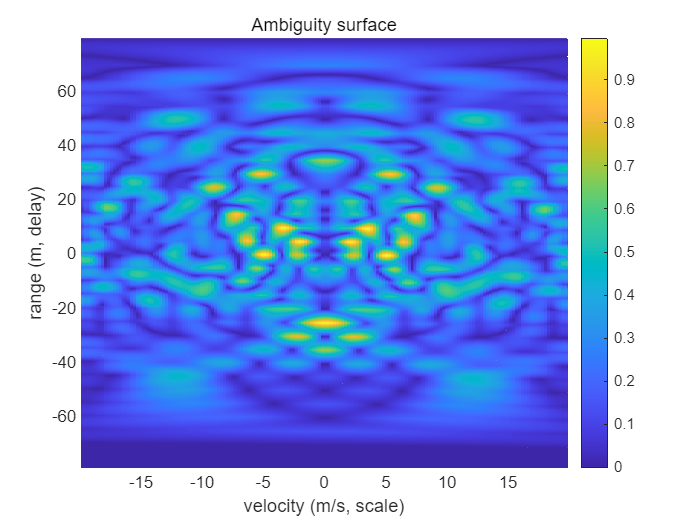

r=50;b=2;len=7;

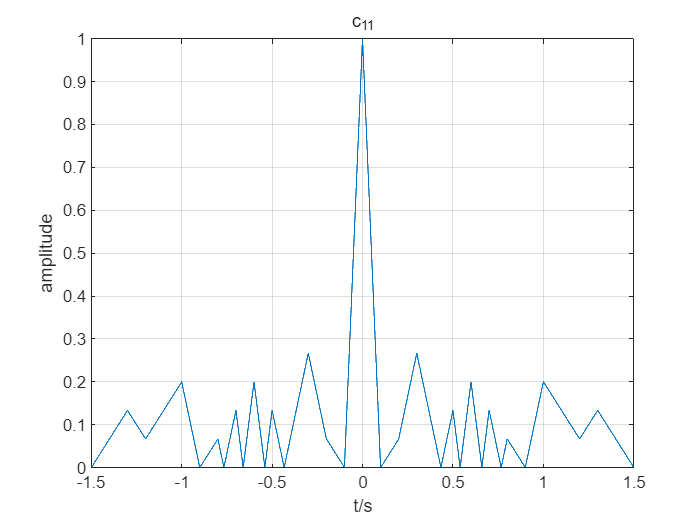

c = 1500;                  %参考速度为1500
v_range = 20;              %定义速度范围
r_range = 1000;            %定义距离范围

%宽带自模糊
[A11, vel] = wideband_ambiguity(kasami_pulse1, kasami_pulse1, r, b, len, c, vmax,r_range , fs);
figure;
N = length(A11); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A11);
xlabel('velocity (m/s, scale)');ylabel('range (m, delay)'); zlabel('magnitude');

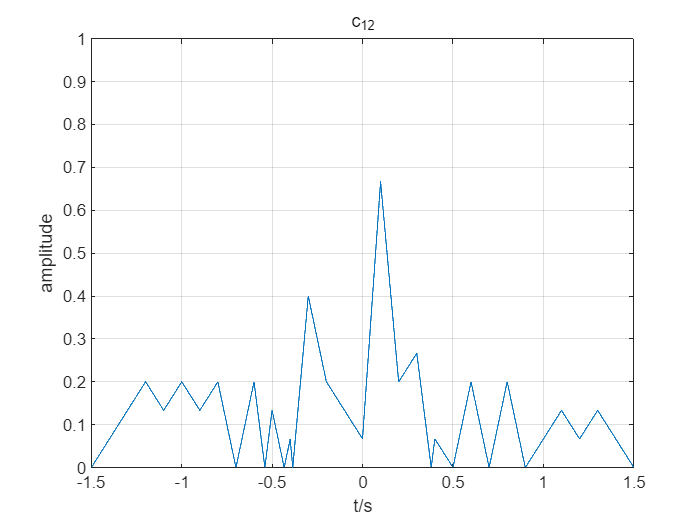

title('Ambiguity surface'); axis tight;
figure
N = length(A11); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A11);
xlabel('velocity (m/s, scale)');ylabel('range (m, delay)'); zlabel('magnitude');
title('Ambiguity surface'); axis tight;
view(0,90);colorbar;

%宽带互模糊1-2

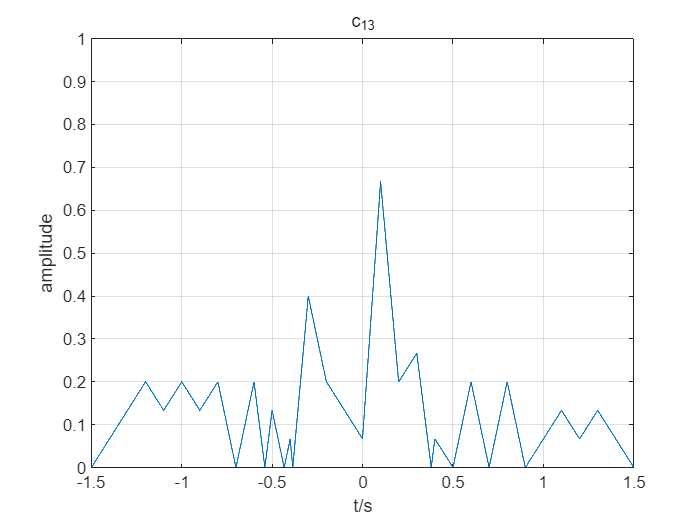

[A12, vel] = wideband_ambiguity(kasami_pulse1, kasami_pulse2, r, b, len, c, vmax,r_range, fs);
figure;
N = length(A12); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A12);
xlabel('velocity (m/s, scale)');ylabel('range (m, delay)'); zlabel('magnitude');
title('Ambiguity surface'); axis tight;
figure
N = length(A11); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A12);
xlabel('velocity (m/s, scale)');ylabel('range (m, delay)'); zlabel('magnitude');

title('Ambiguity surface'); axis tight;
view(0,90);colorbar;

%宽带互模糊1-3
[A13, vel] = wideband_ambiguity(kasami_pulse1, kasami_pulse3, r, b, len, c, vmax,r_range,  fs);
figure;
N = length(A13); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A13);
xlabel('velocity (m/s, scale)');ylabel('range (m, delay)'); zlabel('magnitude');
title('Ambiguity surface'); axis tight;
figure
N = length(A13); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A13);
xlabel('velocity (m/s, scale)');ylabel('range (m, delay)'); zlabel('magnitude');
title('Ambiguity surface'); axis tight;
view(0,90);colorbar;

%计算相关函数
[c11,lags] = xcorr(kasami_pulse1 ,kasami_pulse1);
idx = find(lags>=0,1);%找到第一个大于等于0的索引
c11 = c11./length(kasami_pulse1);
figure
plot(lags*(1/fs),abs(c11));grid on;
xlabel('t/s');ylabel('amplitude');
title('c_{11}');ylim([0,1]);

[c12,lags] = xcorr(kasami_pulse1 ,kasami_pulse2);
idx = find(lags>=0,1);%找到第一个大于等于0的索引
c12 = c12./length(kasami_pulse1);
figure
plot(lags*(1/fs),abs(c12));grid on;title('correlation-c12');ylim([0,1]);
xlabel('t/s');ylabel('amplitude');
title('c_{12}');ylim([0,1]);

[c13,lags] = xcorr(kasami_pulse1 ,kasami_pulse2);
idx = find(lags>=0,1);%找到第一个大于等于0的索引
c13 = c13./length(kasami_pulse1);
figure
plot(lags*(1/fs),abs(c13));grid on;
title('c_{13}');ylim([0,1]);
xlabel('t/s');ylabel('amplitude');

## 信道

###  声速梯度


figure; 
bellhop MunkB_Coh;
plotssp('MunkB_Coh');

根据声速梯度图，当深度为200m时，声速为1530m/s

###     传播损失

%计算传播损失
bellhop 'envs/MunkB_Coh';
figure
plotshd('envs/MunkB_Coh.shd');

绘制声线

figure
bellhop MunkB_ray;
plotray('envs/MunkB_ray.ray');

发射点深度：200m

- 第一声影区：接收点深度400m，距离50767m

- 第一会聚区：接收点深度400m，距离58589m      长度：17000m

- 第二声影区：接收点深度400m，距离107750m

- 第二会聚区：接收点深度400m，距离120000m    长度：22000m

- 第三声影区：接收点深度400m，距离170000m

- 第三会聚区：接收点深度400m，距离181770m     长度：26000m

### 信道的脉冲响应

bellhop计算脉冲响应

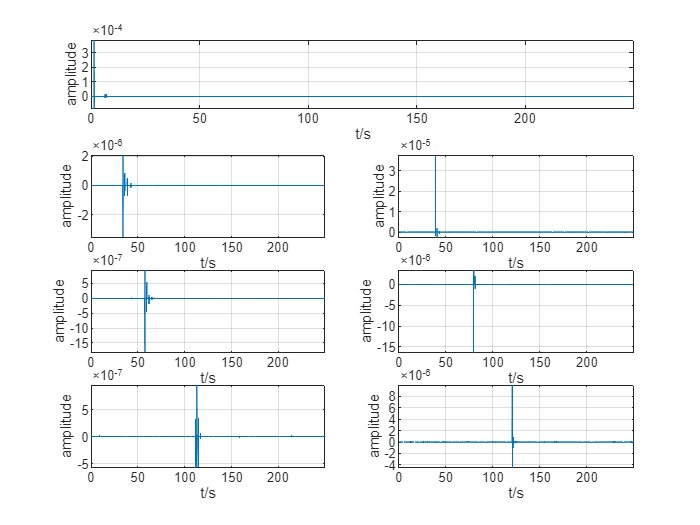

bellhop('envs/direct_Arr');                 %直达区
[direct_arr, ~ ] = read_arrivals_asc('envs/direct_Arr.arr');

bellhop('envs/shadow1_Arr');                %第一声影区
[shadow1_arr, ~ ] = read_arrivals_asc('envs/shadow1_Arr.arr');

bellhop('envs/convergence1_Arr');           %第一会聚区
[convergence1_arr, ~ ] = read_arrivals_asc('envs/convergence1_Arr.arr');
 
bellhop('envs/shadow2_Arr');                %第二声影区
[shadow2_arr, ~ ] = read_arrivals_asc('envs/shadow2_Arr.arr');

bellhop('envs/convergence2_Arr');           %第二会聚区
[convergence2_arr, ~ ] = read_arrivals_asc('envs/convergence2_Arr.arr');

bellhop('envs/shadow3_Arr');                %第三声影区
[ shadow3_arr, ~ ] = read_arrivals_asc('envs/shadow3_Arr.arr');

bellhop('envs/convergence3_Arr');           %第三会聚区
[convergence3_arr, ~ ] = read_arrivals_asc('envs/convergence3_Arr.arr');

t = 0:1/fs:TIME - 1/fs; % 时间向量，这里生成0到200秒的时间序列，采样间隔为1/fs

%获取脉冲响应
%fs：采样频率，时间长度260s

direct_IR = get_IR(direct_arr, fs, TIME);            %直达区脉冲响应
direct_TF = fftshift(fft(direct_IR)).';

shadow1_IR = get_IR(shadow1_arr, fs, TIME);          %第一声影区脉冲响应
shadow1_TF = fftshift(fft(shadow1_IR)).';

convergence1_IR = get_IR(convergence1_arr, fs, TIME); %第一会聚区脉冲响应

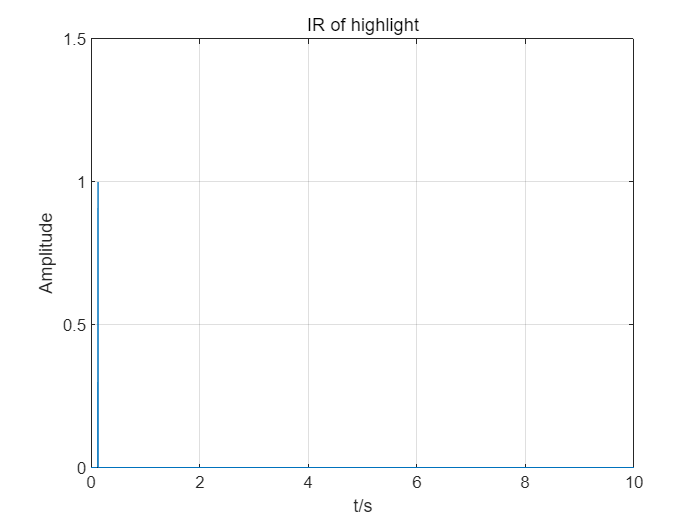

convergence1_TF = fftshift(fft(convergence1_IR)).';

shadow2_IR = get_IR(shadow2_arr, fs, TIME);           %第二声影区脉冲响应
shadow2_TF = fftshift(fft(shadow2_IR)).';

convergence2_IR = get_IR(convergence2_arr, fs, TIME); %第二会聚区脉冲响应
convergence2_TF = fftshift(fft(convergence2_IR)).';

shadow3_IR = get_IR(shadow3_arr, fs, TIME);           %第二声影区脉冲响应
shadow3_TF = fftshift(fft(shadow3_IR)).';

convergence3_IR = get_IR(convergence3_arr, fs, TIME); %第二会聚区脉冲响应
convergence3_TF = fftshift(fft(convergence3_IR)).';

N = length(t);
f = -fs/2:fs/N:fs/2-fs/N;
figure
subplot(4,1,1)
plot(t,direct_IR);grid on;xlabel('t/s');ylabel('amplitude');axis tight;

subplot(4,2,3)

plot(t,shadow1_IR);grid on;xlabel('t/s');ylabel('amplitude');axis tight;

subplot(4,2,4)
plot(t,convergence1_IR);grid on;xlabel('t/s');ylabel('amplitude');axis tight;

subplot(4,2,5)
plot(t,shadow2_IR);grid on;xlabel('t/s');ylabel('amplitude');axis tight;

subplot(4,2,6)
plot(t,convergence2_IR);grid on;xlabel('t/s');ylabel('amplitude');axis tight;
subplot(4,2,7)
plot(t,shadow3_IR);grid on;xlabel('t/s');ylabel('amplitude');axis tight;

subplot(4,2,8)
plot(t,convergence3_IR);grid on;xlabel('t/s');ylabel('amplitude');axis tight;

工具箱绘制脉冲响应

plotarr('direct_Arr.arr',1,1,1);
plotarr('shadow1_Arr.arr',1,1,1);
plotarr('convergence1_Arr.arr',1,1,1);
plotarr('shadow2_Arr.arr',1,1,1);
plotarr('convergence2_Arr.arr',1,1,1);


## 仿真亮点模型

IR_Highlight = zeros(1,round(TIME*fs)).';
IR_Highlight(500) = 1.0+0*1i;
TF_highlight = fftshift(fft(IR_Highlight));

figure
plot(t,IR_Highlight);grid on;
xlabel('t/s');ylabel('Amplitude');
title("IR of highlight");

clear IR_Highlight;axis([0,10,-inf,1.5]);


s1_f = fftshift(fft(paddled1.')).*direct_TF.*TF_highlight;%经过信道到达目标

s2_f = fftshift(fft(paddled1).').*shadow1_TF.*TF_highlight;%目标的转移函数

s3_f = fftshift(fft(paddled1).').*convergence1_TF.*TF_highlight;%目标的转移函数

s4_f = fftshift(fft(paddled1).').*shadow2_TF.*TF_highlight;%目标的转移函数

s5_f = fftshift(fft(paddled1).').*convergence2_TF.*TF_highlight;%目标的转移函数

s6_f = fftshift(fft(paddled1).').*shadow3_TF.*TF_highlight;%目标的转移函数

s7_f = fftshift(fft(paddled1).').*convergence3_TF.*TF_highlight;%目标的转移函数

clear P1 P2 P3;
clear  TF_highlight L b R;

## 信号返回发射点：

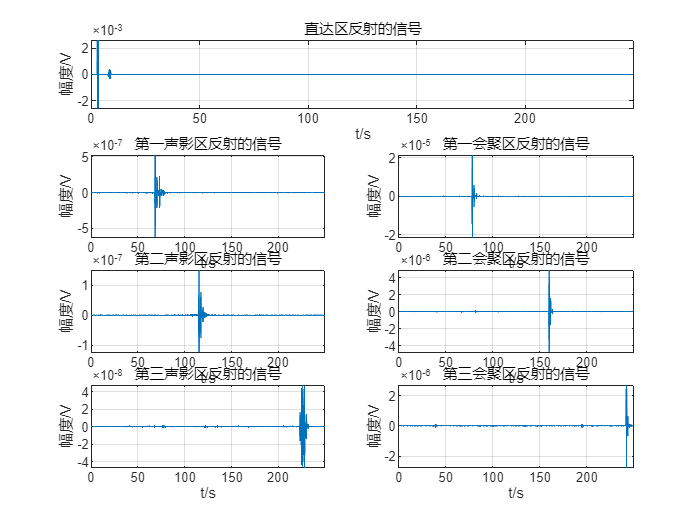

temp = s1_f.*direct_TF;
s1 = ifft(fftshift(temp)).';%交换变量

temp = s2_f.*shadow1_TF;
s2 = ifft(fftshift(temp)).';%交换变量

temp = s3_f.*convergence1_TF;
s3 = ifft(fftshift(temp)).';%交换变量

temp = s4_f.*shadow2_TF;
s4 = ifft(fftshift(temp)).';%交换变量


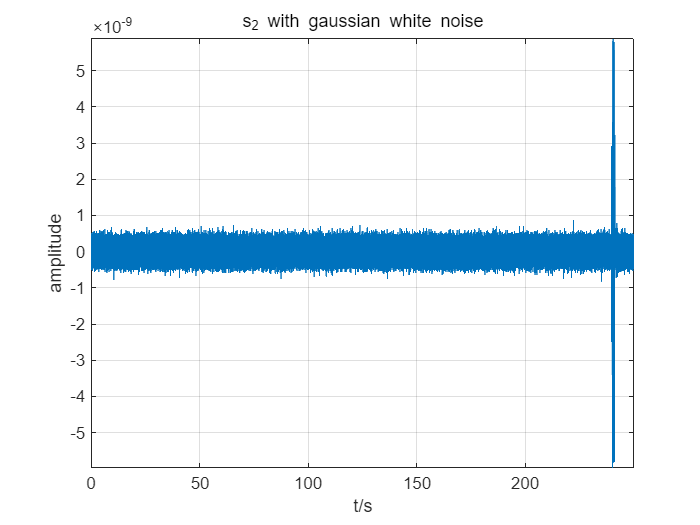

temp = s5_f.*convergence2_TF;
s5 = ifft(fftshift(temp)).';%交换变量

temp = s6_f.*shadow3_TF;
s6 = ifft(fftshift(temp)).';%交换变量

temp = s7_f.*convergence3_TF;
s7 = ifft(fftshift(temp)).';%交换变量
clear s1_f s2_f s3_f s4_f s5_f s6_f s7_f;

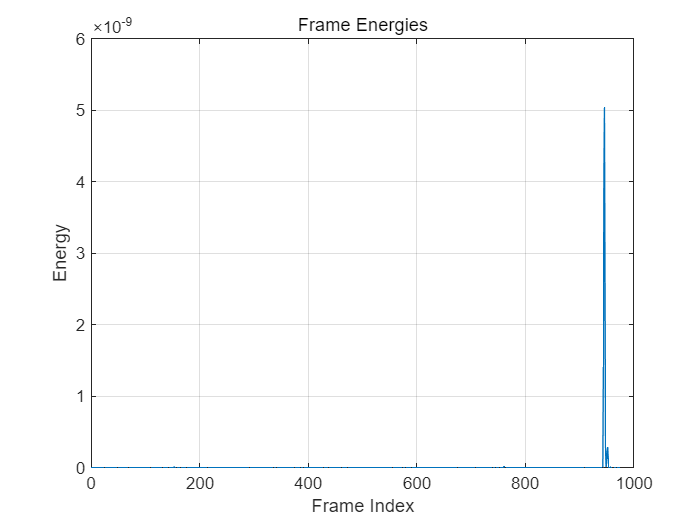

figure
subplot(4,1,1)
plot(t,real(s1));xlabel('t/s');ylabel('幅度/V');grid on;axis tight;
title(sprintf('直达区反射的信号'));
subplot(4,2,3)
plot(t,real(s2));xlabel('t/s');ylabel('幅度/V');grid on;axis tight;
title(sprintf('第一声影区反射的信号'));
subplot(4,2,4)
plot(t,real(s3));xlabel('t/s');ylabel('幅度/V');grid on;axis tight;
title(sprintf('第一会聚区反射的信号'));
subplot(4,2,5)
plot(t,real(s4));xlabel('t/s');ylabel('幅度/V');grid on;axis tight;
title(sprintf('第二声影区反射的信号'));
subplot(4,2,6)
plot(t,real(s5));xlabel('t/s');ylabel('幅度/V');grid on;axis tight;
title(sprintf('第二会聚区反射的信号'));
subplot(4,2,7)
plot(t,real(s6));xlabel('t/s');ylabel('幅度/V');grid on;axis tight;

title(sprintf('第三声影区反射的信号'));
subplot(4,2,8)
plot(t,real(s7));xlabel('t/s');ylabel('幅度/V');grid on;
title(sprintf('第三会聚区反射的信号'));axis tight;

## 添加噪声

SNR = -5;       %设置信噪比 
s2_noisy = awgn(s2,SNR,'measured');s3_noisy = awgn(s3,SNR,'measured');
s4_noisy = awgn(s4,SNR,'measured');s5_noisy = awgn(s5,SNR,'measured');
s6_noisy = awgn(s6,SNR,'measured');s7_noisy = awgn(s7,SNR,'measured');
figure
plot(t,real(s7_noisy));xlabel('t/s');ylabel('amplitude');
grid on;title('s_2 with gaussian white noise');axis tight;

## 检测脉冲

根据能量进行检测

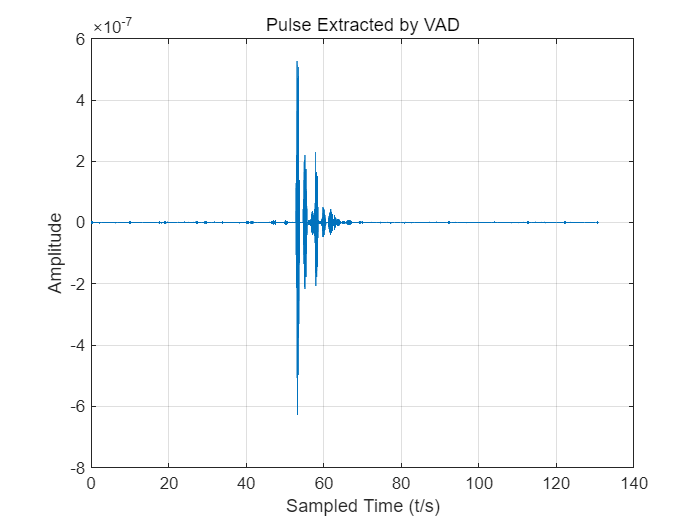

frame_length = 2048;        % 帧长（样本点数）
frame_shift = 1024;         % 帧移（样本点数）

num_frames = floor(length(s2) / frame_shift) - 1;  % 计算帧的数量
frame_energies2 = get_frame_energy(s2,frame_length,frame_shift);
frame_energies3 = get_frame_energy(s3,frame_length,frame_shift);
frame_energies4 = get_frame_energy(s4,frame_length,frame_shift);
frame_energies5 = get_frame_energy(s5,frame_length,frame_shift);

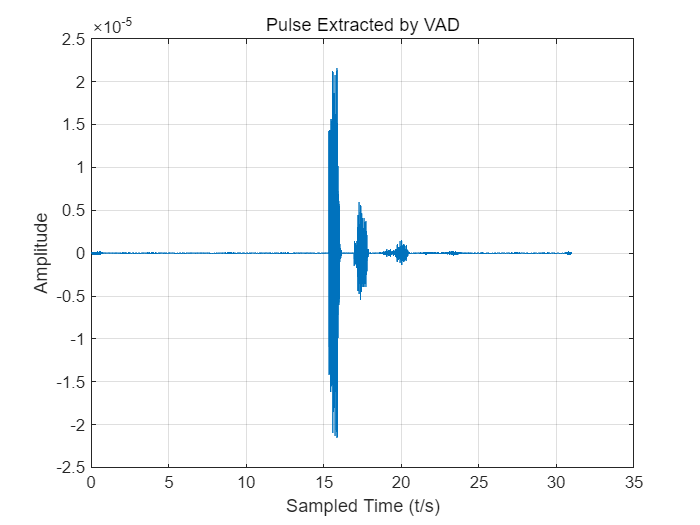

frame_energies6 = get_frame_energy(s6,frame_length,frame_shift);
frame_energies7 = get_frame_energy(s7,frame_length,frame_shift);

% 可视化每帧的能量

figure;
plot(frame_energies7);grid on;
title('Frame Energies');xlabel('Frame Index');ylabel('Energy');
threshold2 = 0.01*mean(frame_energies2);  % 能量阈值（根据实验调整）
threshold3 = 0.01*mean(frame_energies3);
threshold4 = 0.01*mean(frame_energies4);
threshold5 = 0.01*mean(frame_energies5);
threshold6 = 0.01*mean(frame_energies6);
threshold7 = 0.01*mean(frame_energies7);

%如果当前帧的能量大于阈值，获取该帧 
vad_sig2= detect_pulse(s2,frame_energies2,frame_shift,threshold2);

经过第一声影区传播损失为 210.0826dB 
 经过第一会聚区传播损失为 176.0034dB

vad_sig3= detect_pulse(s3,frame_energies3,frame_shift,threshold3);

经过第二声影区传播损失为 221.7458dB 
 经过第二会聚区传播损失为 189.5409dB

vad_sig4= detect_pulse(s4,frame_energies4,frame_shift,threshold4);

经过经过第三声影区传播损失为 227.3646dB 
 经过第三会聚区传播损失为 195.2781dB

vad_sig5= detect_pulse(s5,frame_energies5,frame_shift,threshold5);
vad_sig6= detect_pulse(s6,frame_energies6,frame_shift,threshold6);
vad_sig7= detect_pulse(s7,frame_energies7,frame_shift,threshold7);
figure;
% 可视化提取的脉冲
plot(0:1/fs:(length(vad_sig2)-1)/fs,real(vad_sig2));grid on;
title('Pulse Extracted by VAD');
xlabel('Sampled Time (t/s)');ylabel('Amplitude');xlim auto;
% 可视化提取的脉冲
plot(0:1/fs:(length(vad_sig3)-1)/fs,real(vad_sig3));grid on;
title('Pulse Extracted by VAD');
xlabel('Sampled Time (t/s)');ylabel('Amplitude');xlim auto;

计算能量差

%计算提取的脉冲能量
E_vad2 = sum(abs(vad_sig2).^2);E_vad3 = sum(abs(vad_sig3).^2);
E_vad4 = sum(abs(vad_sig4).^2);E_vad5 = sum(abs(vad_sig5).^2);
E_vad6 = sum(abs(vad_sig6).^2);E_vad7 = sum(abs(vad_sig7).^2);

%计算能量损失
TL2 = 10*log10(E2/E_vad2);TL3 = 10*log10(E2/E_vad3);
TL4 = 10*log10(E2/E_vad4);TL5 = 10*log10(E2/E_vad5);
TL6 = 10*log10(E2/E_vad6);TL7 = 10*log10(E2/E_vad7);
fprintf('经过第一声影区传播损失为 %.4fdB \n 经过第一会聚区传播损失为 %.4fdB',TL2,TL3);
fprintf('经过第二声影区传播损失为 %.4fdB \n 经过第二会聚区传播损失为 %.4fdB',TL4,TL5);
fprintf('经过经过第三声影区传播损失为 %.4fdB \n 经过第三会聚区传播损失为 %.4fdB',TL6,TL7);

## 波束形成

接收到的信号波束形成

考虑阵列情况

d = 1;                  % 阵元间距（10m长的线阵，共10个元素）
eleNum = 10;                 % 阵元数量
angles = -90:10:90;     % 角度范围 -90° 到 90°
alpha = 60;             %阵列的接收角度（0°~180°）

%% 仿真阵元域数据
t = 0:1/fs:TIME-1/fs; % 总时间向量

% beamformed_signals_time_domain1 = beamform(s1.',t,fs,d,c,eleNum,angles,alpha);
% beamformed_signals_time_domain2 = beamform(s2.',t,fs,d,c,eleNum,angles,alpha);
% beamformed_signals_time_domain3 = beamform(s3.',t,fs,d,c,eleNum,angles,alpha);
% beamformed_signals_time_domain4 = beamform(s4.',t,fs,d,c,eleNum,angles,alpha);
% beamformed_signals_time_domain5 = beamform(s5.',t,fs,d,c,eleNum,angles,alpha);
beamformed_signals_time_domain6 = beamform(s6.',t,fs,d,c,eleNum,angles,alpha);
beamformed_signals_time_domain7 = beamform(s7.',t,fs,d,c,eleNum,angles,alpha);

## 波束处理后的接收信号

波束角度60°

% s1_beam60 = beamformed_signals_time_domain1(7,:);
% s2_beam60 = beamformed_signals_time_domain2(7,:);
% s3_beam60 = beamformed_signals_time_domain3(7,:);
% s4_beam60 = beamformed_signals_time_domain4(7,:);
% s5_beam60 = beamformed_signals_time_domain5(7,:);
s6_beam60 = beamformed_signals_time_domain6(7,:);
s7_beam60 = beamformed_signals_time_domain7(7,:);
clear beamformed_signals_time_domain1 beamformed_signals_time_domain2 beamformed_signals_time_domain3;
clear beamformed_signals_time_domain4 beamformed_signals_time_domain5 beamformed_signals_time_domain6;
clear beamformed_signals_time_domain7;
clear s1 s2 s3 s4 s5 s6;
figure
subplot(3,1,1)
plot(t,real(s1_beam60));xlabel('t/s');ylabel('Am');grid on;
subplot(3,1,2)
plot(t,real(s2_beam60));xlabel('t/s');ylabel('Am');grid on;
subplot(3,1,3)
plot(t,real(s3_beam60));xlabel('t/s');ylabel('Am');grid on;

## 匹配滤波

时域信号


[r1,lags] = xcorr(s1 ,matchedFilter1);
idx = find(lags>=0,1);%找到第一个大于等于0的索引
r1 = r1(idx:end);
lags = lags(idx:end);    

[r2,~] = xcorr(s2,matchedFilter1);
r2 = r2(idx:end);

[r3,~] = xcorr(s3 ,matchedFilter1);
r3 = r3(idx:end);

[r4,~] = xcorr(s4 ,matchedFilter1);
r4 = r4(idx:end);

[r5,~] = xcorr(s5 ,matchedFilter1);
r5 = r5(idx:end);

[r6,~] = xcorr(s6 ,matchedFilter1);
r6 = r6(idx:end);

[r7,~] = xcorr(s7 ,matchedFilter1);
r7 = r7(idx:end);

clear  temp;

figure
subplot(4,1,1)
plot(lags*(1/fs),real(r1));xlabel('t/s');ylabel('Am');grid on;title('direct area');
subplot(4,2,3)
plot(lags*(1/fs),real(r2));xlabel('t/s');ylabel('Am');grid on;title('1st shadow zone');
subplot(4,2,4)
plot(lags*(1/fs),real(r3));xlabel('t/s');ylabel('Am');grid on;title('1st convergence zone');

subplot(4,2,5)
plot(lags*(1/fs),real(r4));xlabel('t/s');ylabel('Am');grid on;title('2nd shadow zone');
subplot(4,2,6)
plot(lags*(1/fs),real(r5));xlabel('t/s');ylabel('Am');grid on;title('2nd convergence zone');

subplot(4,2,7) 
plot(lags*(1/fs),real(r6));xlabel('t/s');ylabel('Am');grid on;title('3rd shadow zone');
subplot(4,2,8)
plot(lags*(1/fs),real(r7));xlabel('t/s');ylabel('Am');grid on;title('3rd convergence zone');
t = 0:1/fs:TIME-1/fs;
s1 = gather(r1);
s2 = gather(r2);
s3 = gather(r3);
clear r1 r2 r3;
% s1 = gather(s1_beam60);
% s2 = gather(s2_beam60);
% s3 = gather(s3_beam60);

时频

audiowrite('audios/kasami_cw_direct.wav',real(s1)./max(abs(real(s1))),4e3);
audiowrite('audios/kasami_cw_1st_shadow.wav',real(s2)./max(abs(real(s2))),4e3);
audiowrite('audios/kasami_cw_1st_convergence.wav',real(s3)./max(abs(real(s3))),fs);
audiowrite('audios/kasami_cw_2nd_shadow.wav',real(s4)./max(abs(real(s4))),fs);
audiowrite('audios/kasami_cw_2nd_convergence.wav',real(s5)./max(abs(real(s5))),fs);
audiowrite('audios/kasami_cw_3rd_shadow.wav',real(s6)./max(abs(real(s6))),fs);
audiowrite('audios/kasami_cw_3rd_convergence.wav',real(s7)./max(abs(real(s7))),fs);